%Iqbal Luqmanul Hakim 
%082111733063
clc; clear all;
x = [0 1 2 2.5 3];
y = [2.9 3.7 4.1 4.4 5];

jumx = 0;
jumxx = 0;
jumy = 0;
jumxy = 0;

for i = 1:5
    jumx = jumx + x(i);
    jumxx = jumxx + (x(i) ^ 2);
    jumy = jumy + y(i);
    jumxy = jumxy + (y(i) * x(i));
end

A = [5 jumx; jumx jumxx];
B = [jumy; jumxy];

C = inv(A) * B;

disp('Tabel Nilai:');

Tabel Nilai:


disp('--------------------------------------');

--------------------------------------


disp('   x     |    y    |   xy   |   x^2  ');

   x     |    y    |   xy   |   x^2  


disp('--------------------------------------');

--------------------------------------


for i = 1:5
    disp([x(i), y(i), x(i) * y(i), x(i) ^ 2]);
end

         0    2.9000         0         0

    1.0000    3.7000    3.7000    1.0000

    2.0000    4.1000    8.2000    4.0000

    2.5000    4.4000   11.0000    6.2500

     3     5    15     9



disp('--------------------------------------');

--------------------------------------


disp(['JumX  = ', num2str(jumx)]);

JumX  = 8.5


disp(['JumXY = ', num2str(jumxy)]);

JumXY = 37.9


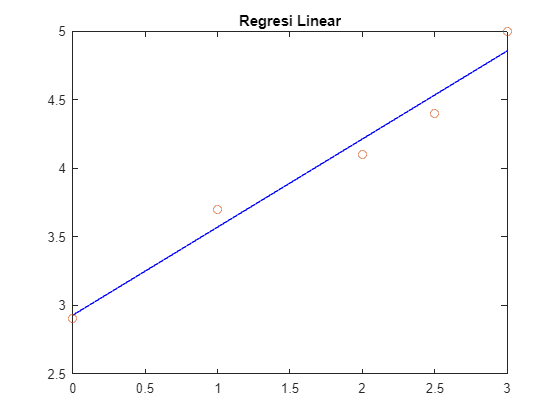


for i = 1:5
    f2(i) = C(2) * x(i) + C(1);
end

plot(x, f2, 'b', x, y, 'o');
title('Regresi Linear');